**Extended Kalman Filter**

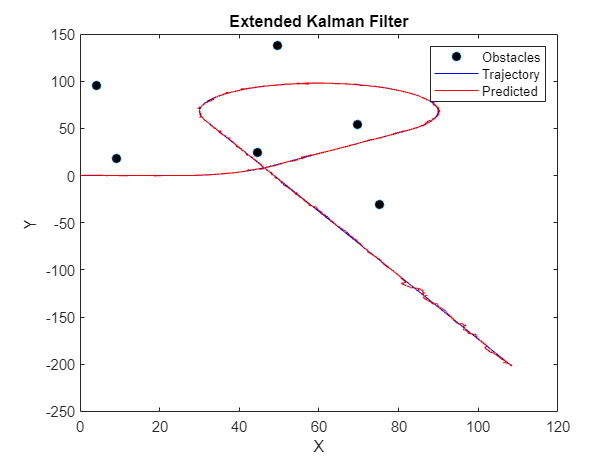

clear;
close all;

trajectory = readtable('lab4_dataset_traj.csv');
landmarks = readtable('lab4_dataset_landmarks.csv');
odometry = readtable('lab4_dataset_odometry.csv');
sensors = readtable('lab4_dataset_sensors.csv');

x = [0; 0; 0];
l = 0.1;

V = [1 0; 0 1];
P = [10, 0, 0; 0, 10, 0; 0, 0, pi^2];
wr = 0.5^2;
wbeta = (10*pi/180)^2;
W = diag([wr wbeta wr wbeta wr wbeta wr wbeta wr wbeta wr wbeta]);

predictionsX = zeros(1000, 1);
predictionsY = zeros(1000, 1);
pNorm = zeros(1000, 1);
pNorm(1) = norm(P);
poses = zeros(1000, 3);
poses(1, 1) = x(1);
poses(1, 2) = x(2);
poses(1, 3) = x(3);

for i=1:999
    x(3) = wrapToPi(x(3));
    [x_predicted, p_predicted] = EKFPrediction(x, odometry.DeltaSR(i), odometry.DeltaSL(i), l, V, P);
    [x, P] = EKFCorrection(i+1, x_predicted, p_predicted, landmarks, sensors, W);
    predictionsX(i+1) = x_predicted(1);
    predictionsY(i+1) = x_predicted(2);
    pNorm(i+1) = norm(P);
    poses(i+1, 1) = x(1);
    poses(i+1, 2) = x(2);
    poses(i+1, 3) = x(3);
end

figure;
plot(landmarks.xL, landmarks.yL, 'o', 'MarkerFaceColor', 'black');
hold on;
plot(trajectory.x, trajectory.y, 'blue');
plot(predictionsX, predictionsY, 'red');
legend('Obstacles', 'Trajectory', 'Predicted');
title('Extended Kalman Filter');
xlabel('X');
ylabel('Y');
hold off;

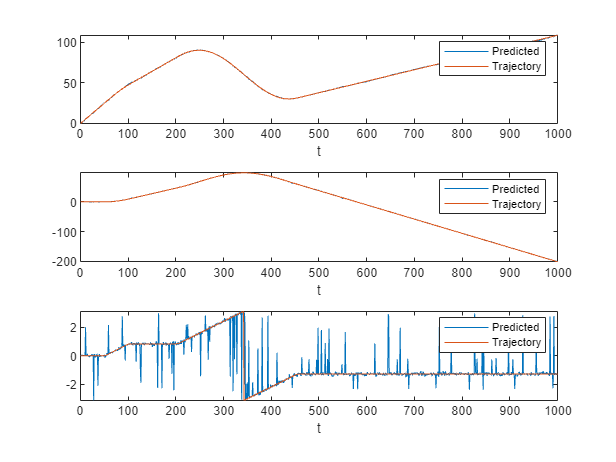


% Plot motion
%figure;
%plot(pNorm);
%xlabel('Time step');
%ylabel('Magnitude')
%title('State Prediction Covariance')

% Plot difference in poses
figure;
% x position
subplot(3, 1, 1);
title('X position');
xlabel('t');
plot(poses(:, 1));
hold on;
plot(trajectory.x);
hold off;
legend('Predicted', 'Trajectory');
xlabel('t');
% y position
subplot(3, 1, 2);
title('Y position');
plot(poses(:, 2));
hold on;
plot(trajectory.y);
hold off;
legend('Predicted', 'Trajectory');
xlabel('t');
% Theta
subplot(3, 1, 3);
title('Theta');
plot(poses(:, 3));
hold on;
plot(wrapToPi(trajectory.theta));
hold off;
legend('Predicted', 'Trajectory');
xlabel('t');

**Jacobians**

function out_Fx = JacobianFx(in_x, in_sr, in_sl)
out_Fx = [
    1 0 -(in_sr + in_sl) * 0.5 * sin(in_x(3));
    0 1 (in_sr + in_sl) * 0.5 * cos(in_x(3));
    0 0 1
];
end

function out_Fv = JacobianFv(in_x)
out_Fv = [
    cos(in_x(3)) 0;
    sin(in_x(3)) 0;
    0 1
];
end

**Prediction & Correction**

function [out_x, out_p] = EKFPrediction(in_x, in_sr, in_sl, in_l, in_V, in_P)

dx = ((in_sr + in_sl) * 0.5) * cos(in_x(3));
dy = ((in_sr + in_sl) * 0.5) * sin(in_x(3));
dtheta = (in_sr - in_sl) / in_l;

Fx = JacobianFx(in_x, in_sr, in_sl);
Fv = JacobianFv(in_x);

out_x = in_x + [dx; dy; dtheta];
out_x(3) = wrapToPi(out_x(3));

out_p = Fx*in_P*Fx' + Fv*in_V*Fv';
end

function [out_x, out_p] = EKFCorrection(k, in_x_predicted, in_P, in_landmarks, in_sensors, in_W)
Hw = eye(12);
Hx = CalculateHx(in_x_predicted, in_landmarks);
v = EKFInnovation(k, in_x_predicted, in_landmarks, in_sensors);
kalmanGain = CalculateKalmanGain(in_P, Hx, Hw, in_W);

out_x = in_x_predicted + kalmanGain * v;
out_x(3) = wrapToPi(out_x(3));
out_p = in_P - kalmanGain * Hx * in_P;

end

function k = CalculateKalmanGain(in_P, in_Hx, in_Hw, in_W)
    k = in_P * in_Hx' * inv(in_Hx * in_P * in_Hx' + in_Hw * in_W * in_Hw');
end

function Hx = CalculateHx(in_x_predicted, in_landmarks)

    r = [
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(1), in_landmarks.yL(1));
        Distance(in_x_predicted(2), in_x_predicted(2), in_landmarks.xL(2), in_landmarks.yL(2));
        Distance(in_x_predicted(2), in_x_predicted(2), in_landmarks.xL(3), in_landmarks.yL(3));
        Distance(in_x_predicted(2), in_x_predicted(2), in_landmarks.xL(4), in_landmarks.yL(4));
        Distance(in_x_predicted(2), in_x_predicted(2), in_landmarks.xL(5), in_landmarks.yL(5));
        Distance(in_x_predicted(2), in_x_predicted(2), in_landmarks.xL(6), in_landmarks.yL(6));
    ];

    Hx = [
        % Landmarks 1
        -(in_landmarks.xL(1) - in_x_predicted(1)) / r(1), -(in_landmarks.yL(1) - in_x_predicted(2)) / r(1), 0;
        (in_landmarks.yL(1) - in_x_predicted(2)) / r(1)^2, -(in_landmarks.xL(1) - in_x_predicted(1)) / r(1)^2, -1;

        % Landmarks 2
        -(in_landmarks.xL(2) - in_x_predicted(1)) / r(2), -(in_landmarks.yL(2) - in_x_predicted(2)) / r(2), 0;
        (in_landmarks.yL(2) - in_x_predicted(2)) / r(2)^2, -(in_landmarks.xL(2) - in_x_predicted(1)) / r(2)^2, -1;

        % Landmarks 3
        -(in_landmarks.xL(3) - in_x_predicted(1)) / r(3), -(in_landmarks.yL(3) - in_x_predicted(2)) / r(3), 0;
        (in_landmarks.yL(3) - in_x_predicted(2)) / r(3)^2, -(in_landmarks.xL(3) - in_x_predicted(1)) / r(3)^2, -1;

        % Landmarks 4
        -(in_landmarks.xL(4) - in_x_predicted(1)) / r(4), -(in_landmarks.yL(4) - in_x_predicted(2)) / r(4), 0;
        (in_landmarks.yL(4) - in_x_predicted(2)) / r(4)^2, -(in_landmarks.xL(4) - in_x_predicted(1)) / r(4)^2, -1;
    
        % Landmarks 5
        -(in_landmarks.xL(5) - in_x_predicted(1)) / r(5), -(in_landmarks.yL(5) - in_x_predicted(2)) / r(5), 0;
        (in_landmarks.yL(5) - in_x_predicted(2)) / r(5)^2, -(in_landmarks.xL(5) - in_x_predicted(1)) / r(5)^2, -1;
        
        % Landmarks 6
        -(in_landmarks.xL(6) - in_x_predicted(1)) / r(6), -(in_landmarks.yL(6) - in_x_predicted(2)) / r(6), 0;
        (in_landmarks.yL(6) - in_x_predicted(2)) / r(6)^2, -(in_landmarks.xL(6) - in_x_predicted(1)) / r(6)^2, -1;
    ];

end

function d = Distance(x, y, xL, yL)
    d = sqrt((yL - y)^2 + (xL - x)^2);
end

function theta = Angle(x, y, xL, yL)
    theta = atan2((yL-y), (xL - x));
end

function v = EKFInnovation(k, in_x_predicted, in_landmarks, in_sensors)

    h = [
        % Landmark 1
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(1), in_landmarks.yL(1));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(1), in_landmarks.yL(1)) - in_x_predicted(3);

        % Landmark 2
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(2), in_landmarks.yL(2));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(2), in_landmarks.yL(2)) - in_x_predicted(3);
        
        % Landmark 3
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(3), in_landmarks.yL(3));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(3), in_landmarks.yL(3)) - in_x_predicted(3);

        % Landmark 4
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(4), in_landmarks.yL(4));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(4), in_landmarks.yL(4)) - in_x_predicted(3);

        % Landmark 5
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(5), in_landmarks.yL(5));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(5), in_landmarks.yL(5)) - in_x_predicted(3);

        % Landmark 6
        Distance(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(6), in_landmarks.yL(6));
        Angle(in_x_predicted(1), in_x_predicted(2), in_landmarks.xL(6), in_landmarks.yL(6)) - in_x_predicted(3);
    ];

    z = [
        % Landmark 1
        in_sensors.r1(k);
        in_sensors.th1(k);

        % Landmark 2
        in_sensors.r2(k);
        in_sensors.th2(k);
        
        % Landmark 3
        in_sensors.r3(k);
        in_sensors.th3(k);
    
        % Landmark 4
        in_sensors.r4(k);
        in_sensors.th4(k);

        % Landmark 5
        in_sensors.r5(k);
        in_sensors.th5(k);

        % Landmark 6
        in_sensors.r6(k);
        in_sensors.th6(k);
    ];

    [rows, ~] = size(h);
    for n = 2:2:rows
        h(n) = wrapToPi(h(n));
    end

    v = z - h;

    [rows, ~] = size(v);
    for n = 2:2:rows
        v(n) = wrapToPi(v(n));
    end

end